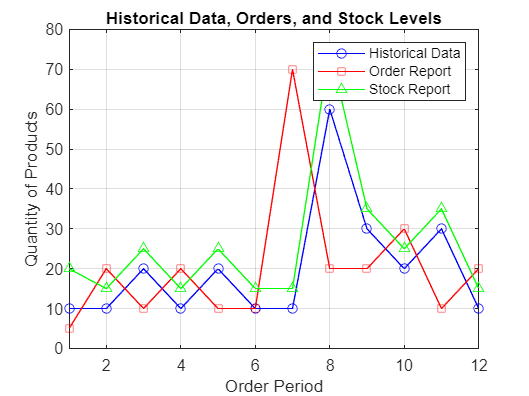

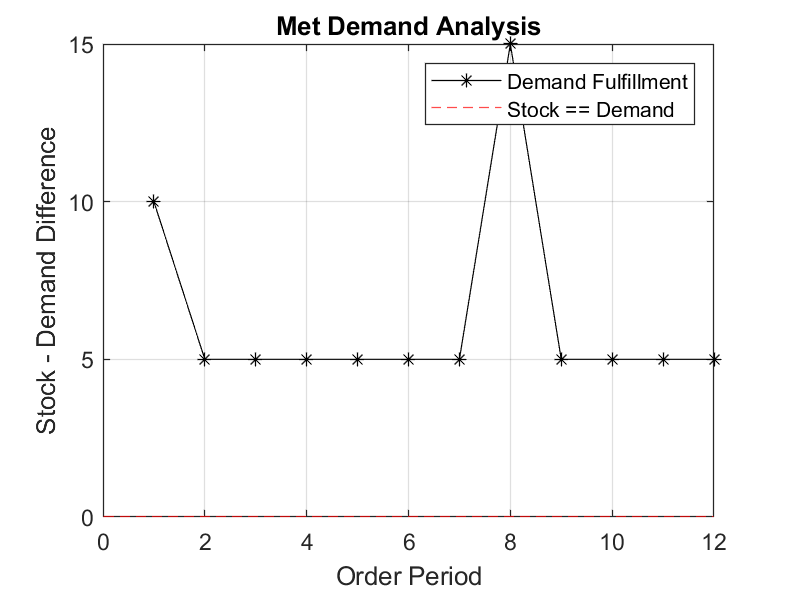

% Main script for demand forecasting

%% User settings for the script
% These parameters control the behavior of the forecasting model
orderSize = 20;           % Default size of each order
numOfOrders = 12;         % Number of orders per year
initialNumOfProducts = 20; % Initial stock of products
maxProductsHeld = 70;     % Maximum allowable stock
minOrderSize = 5;         % Minimum allowable order size
maxError = 5;             % Maximum acceptable error between stock and demand
bufferStock = 5;          % Additional buffer stock to handle unexpected demand

%% Initialize historical and current data
% Historical data represents past sales; current data is for recent trends
historicalData = 10 .* [1, 1, 2, 1, 2, 1, 1, 6, 3, 2, 3, 1];
currentData = 10 .* [1, 2, 2, 2, 2, 1, 2, 5, 4, 2, 2, 1];

%% Call the order forecast function
% Generates the order and stock report based on historical data
forecast1 = orderForecast(historicalData, initialNumOfProducts, orderSize, ...
    minOrderSize, numOfOrders, true, ...
    maxProductsHeld, bufferStock);

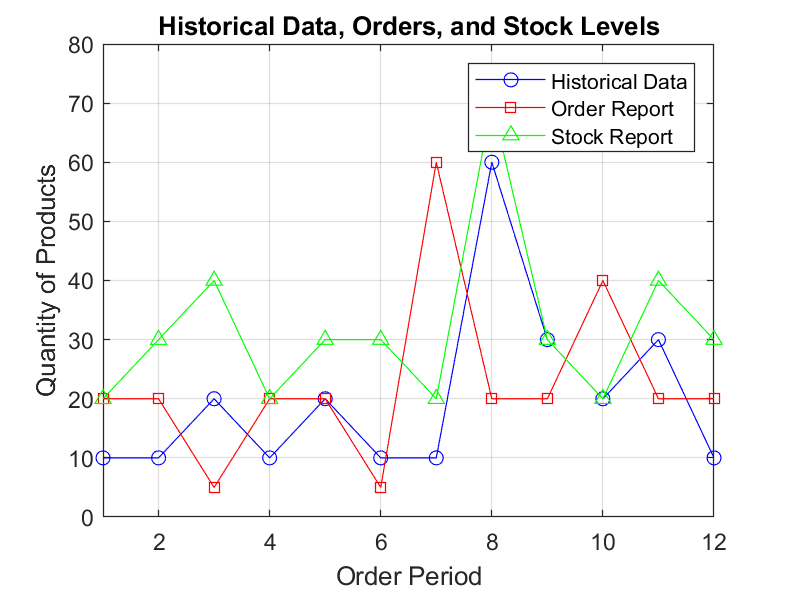

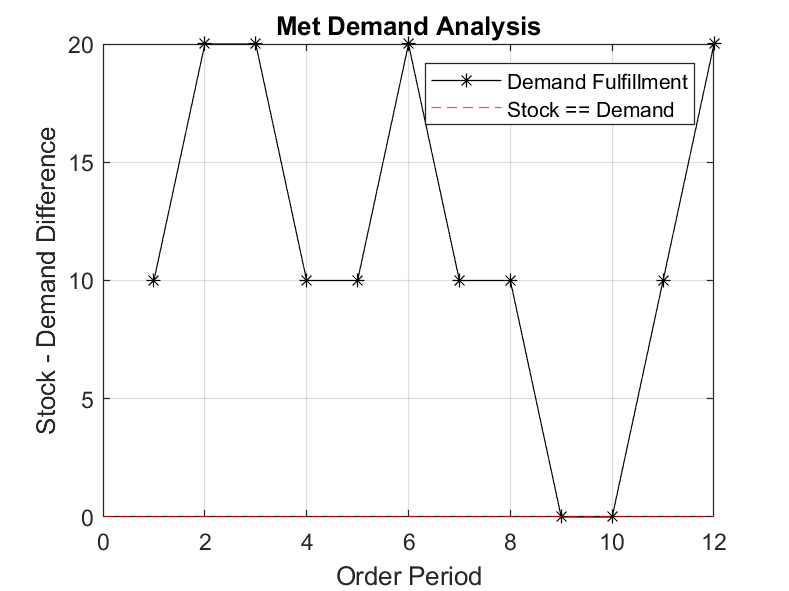

forecast2 = orderForecast(historicalData, initialNumOfProducts, orderSize, ...
    minOrderSize, numOfOrders, false, ...
    maxProductsHeld, bufferStock);

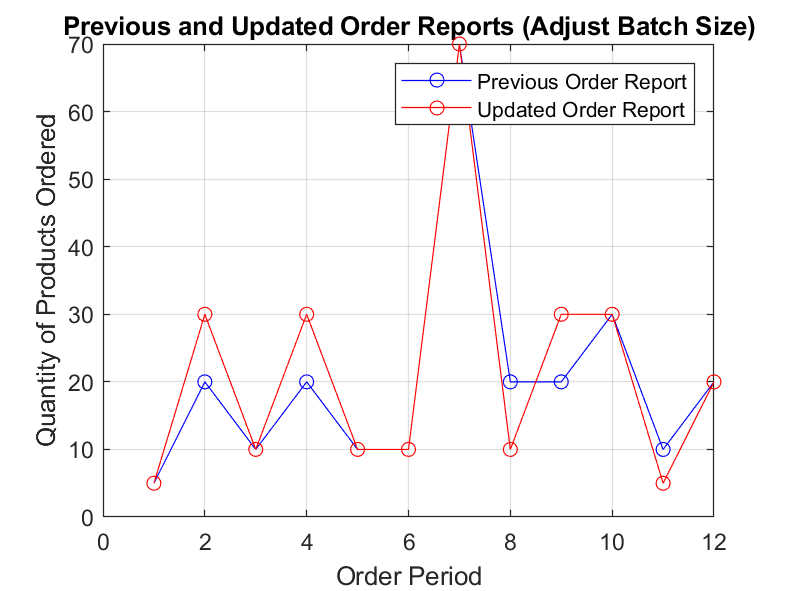


%% Process updated forecasts for dynamic adjustments
% Forecast using dynamic adjustment for updated sales trends
updatedOrderReport1 = forecast1;
updatedStockReport1 = zeros(length(historicalData), 1); % Tracks stock levels
updatedStockReport1(1) = initialNumOfProducts;         % Set the initial stock levels

for i = 1:length(currentData)
    dataPoint = currentData(i);
    updatedOrderReport1 = dynamicForecast(historicalData, dataPoint, updatedOrderReport1, ...
                                         updatedStockReport1(i), orderSize, minOrderSize, ...
                                         maxError, maxProductsHeld, true, i);
    if i < 12
        % Update stock level for the next period
        updatedStockReport1(i + 1) = updatedStockReport1(i) + updatedOrderReport1(i) - currentData(i);
        % Prevent negative stock levels by enforcing a minimum of zero
        updatedStockReport1(i + 1) = max(updatedStockReport1(i + 1), 0);
    end
end

%% Process stock levels for adjusted order frequency
updatedOrderReport2 = forecast2;
updatedStockReport2 = zeros(length(historicalData), 1); % Tracks stock levels
updatedStockReport2(1) = initialNumOfProducts;         % Set the initial stock level

for i = 1:length(currentData)
    dataPoint = currentData(i);
    updatedOrderReport2 = dynamicForecast(historicalData, dataPoint, updatedOrderReport2, ...
                                         initialNumOfProducts, orderSize, minOrderSize, ...
                                         maxError, maxProductsHeld, false, i);
    if i < 12
        % Update stock level for the next period
        updatedStockReport2(i + 1) = updatedStockReport2(i) + updatedOrderReport2(i) - currentData(i);
        % Prevent negative stock levels by enforcing a minimum of zero
        updatedStockReport2(i + 1) = max(updatedStockReport2(i + 1), 0);
    end
end

%% Plot previous and updated order reports (adjusted batch size and order frequency)
figure;
plot(1:length(forecast1), forecast1, 'b-o', 'DisplayName', 'Previous Order Report');
hold on;
plot(1:length(updatedOrderReport1), updatedOrderReport1, 'r-o', 'DisplayName', 'Updated Order Report');
legend;
title('Previous and Updated Order Reports (Adjust Batch Size)');
xlabel('Order Period');
ylabel('Quantity of Products Ordered');
grid on;

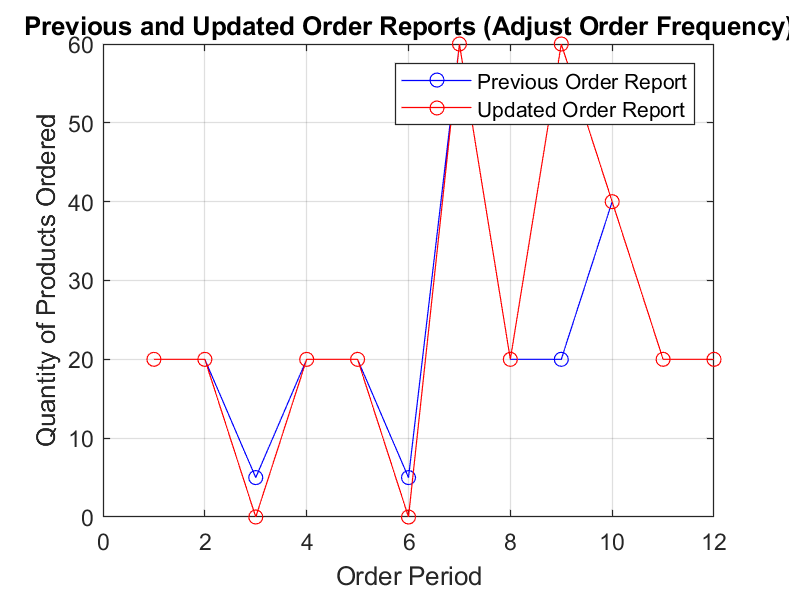


figure;
plot(1:length(forecast2), forecast2, 'b-o', 'DisplayName', 'Previous Order Report');
hold on;
plot(1:length(updatedOrderReport2), updatedOrderReport2, 'r-o', 'DisplayName', 'Updated Order Report');
legend;
title('Previous and Updated Order Reports (Adjust Order Frequency)');
xlabel('Order Period');
ylabel('Quantity of Products Ordered');
grid on;

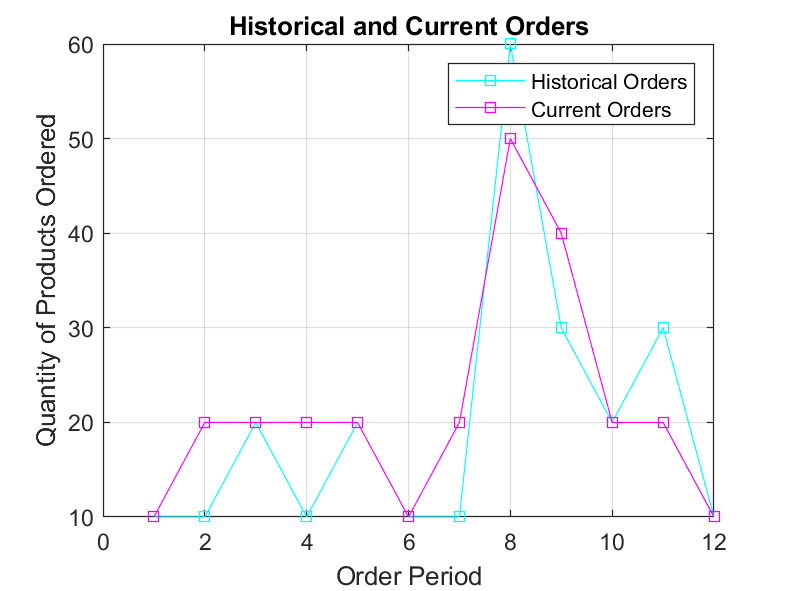


%% Plot historical and current orders for comparison
figure;
plot(1:length(historicalData), historicalData, 'c-s', 'DisplayName', 'Historical Orders');
hold on;
plot(1:length(currentData), currentData, 'm-s', 'DisplayName', 'Current Orders');
legend;
title('Historical and Current Orders');
xlabel('Order Period');
ylabel('Quantity of Products Ordered');
grid on;

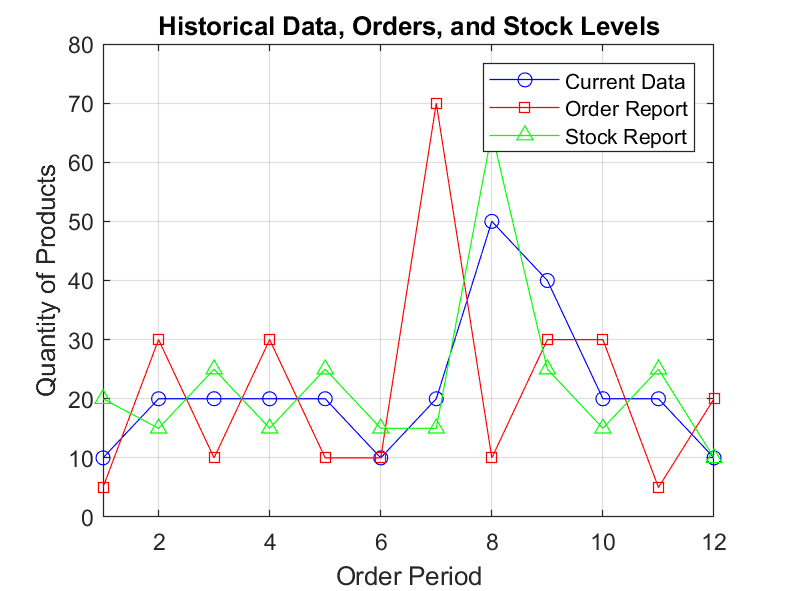


%% Plot historical demand, order report, and stock report (for dynamic adjustment)
figure;
plot(1:length(currentData), currentData, 'b-o', 'DisplayName', 'Current Data'); % Current demand
hold on;
plot(1:length(updatedOrderReport1), updatedOrderReport1, 'r-s', 'DisplayName', 'Order Report'); % Orders placed
hold on;
plot(1:length(updatedStockReport1), updatedStockReport1, 'g-^', 'DisplayName', 'Stock Report'); % Stock levels
legend;
title('Historical Data, Orders, and Stock Levels');
xlabel('Order Period');
ylabel('Quantity of Products');
axis([1 length(historicalData) 0 maxProductsHeld + 10]); % Adjust axis limits
grid on;

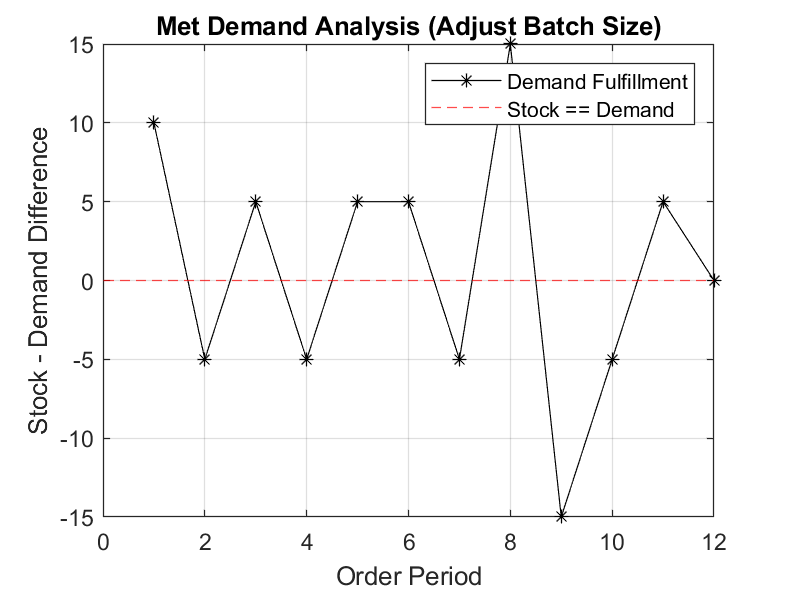


%% Plot demand fulfillment analysis (dynamic adjustment)
metDemand = updatedStockReport1 - transpose(currentData);
figure;
plot(1:length(metDemand), metDemand, 'k-*', 'DisplayName', 'Demand Fulfillment'); % Stock-demand difference
hold on;
yline(0, '--r', 'DisplayName', 'Stock == Demand'); % Reference line where stock meets demand
legend;
title('Met Demand Analysis (Adjust Batch Size)');
xlabel('Order Period');
ylabel('Stock - Demand Difference');
grid on;

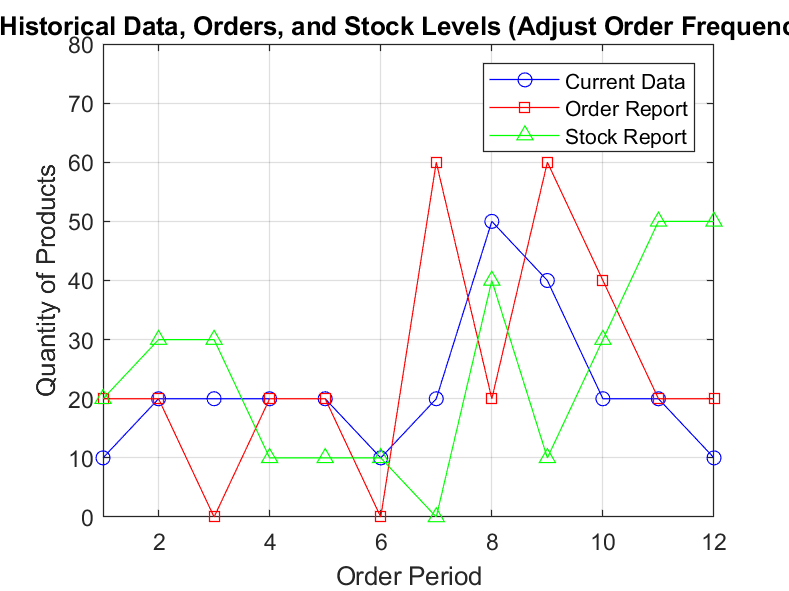


%% Plot stock reports for adjusted order frequency
figure;
plot(1:length(currentData), currentData, 'b-o', 'DisplayName', 'Current Data'); % Current demand
hold on;
plot(1:length(updatedOrderReport2), updatedOrderReport2, 'r-s', 'DisplayName', 'Order Report'); % Orders placed
hold on;
plot(1:length(updatedStockReport2), updatedStockReport2, 'g-^', 'DisplayName', 'Stock Report'); % Stock levels
legend;
title('Historical Data, Orders, and Stock Levels (Adjust Order Frequency)');
xlabel('Order Period');
ylabel('Quantity of Products');
axis([1 length(historicalData) 0 maxProductsHeld + 10]); % Adjust axis limits
grid on;

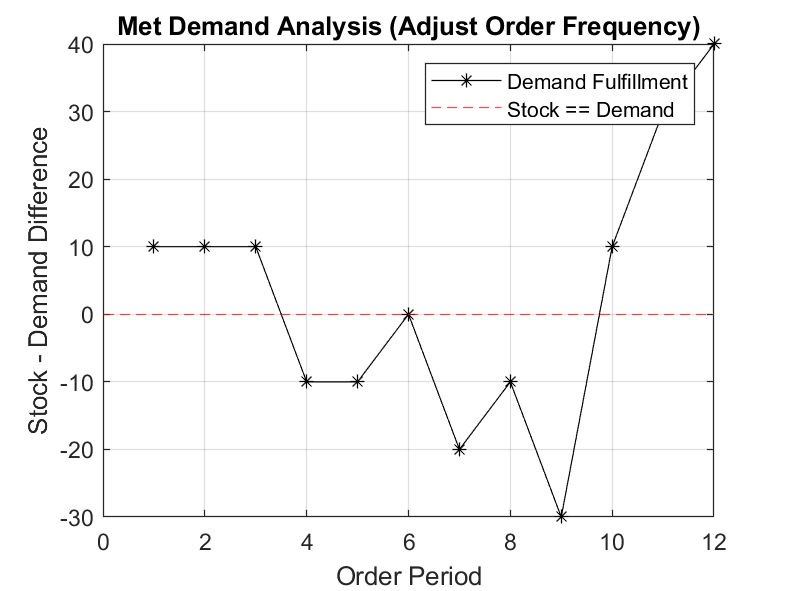


%% Plot demand fulfillment analysis (adjust order frequency)
metDemand = updatedStockReport2 - transpose(currentData);
figure;
plot(1:length(metDemand), metDemand, 'k-*', 'DisplayName', 'Demand Fulfillment'); % Stock-demand difference
hold on;
yline(0, '--r', 'DisplayName', 'Stock == Demand'); % Reference line where stock meets demand
legend;
title('Met Demand Analysis (Adjust Order Frequency)');
xlabel('Order Period');
ylabel('Stock - Demand Difference');
grid on;